# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.7 知乎提问

#### 2.7.18 matlab中如何绘制三维曲面图，并对曲面颜色进行部分区域修改？

原问题：[https://www.zhihu.com/question/661910106](https://www.zhihu.com/question/661910106)

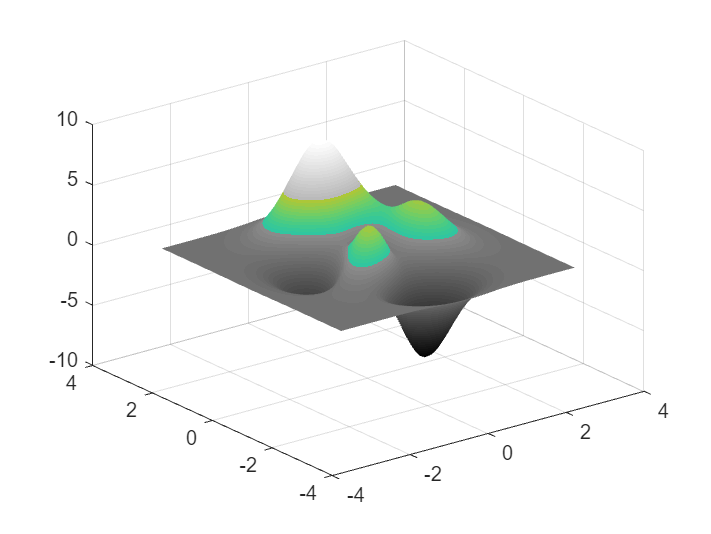

clear;clc;
[x, y, z] = peaks(50);
% 把下面这个范围的值用另一种颜色表示
z_max = max(z(:));
z_min = min(z(:));
z_down = 0.2 * z_max;
z_up = 0.5 * z_max;
% 定义一个 colormap
map1 = gray(64);
map2 = parula(64);
% 整合一个新的
idx1 = (z_down - z_min) / (z_max - z_min)* 64;
idx1 = int32(idx1);
idx2 = (z_up - z_min) / (z_max - z_min)* 64;
idx2 = int32(idx2);
idxs = (1:64)';
map3 = map1 .* repmat(idxs < idx1, 1, 3) + ...
       map2 .* repmat(idxs >= idx1 & idxs <= idx2, 1, 3) + ...
       map1 .* repmat(idxs > idx2, 1, 3);
surf(x, y, z);
colormap(map3);
shading interp

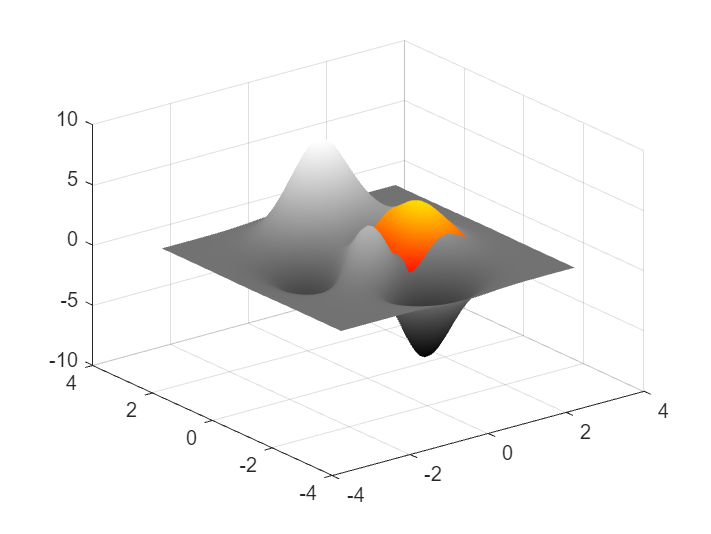


figure;
z1 = z;
% 第一幅图不显示指定范围
x_range = 20:30;
y_range = 30:40;
x_range2 = 19:31;
y_range2 = 29:41;
z1(x_range, y_range) = NaN;
% 第二幅图只显示指定范围
z2 = nan(50);
z2(x_range2, y_range2) = z(x_range2, y_range2);
surf(x, y, z1);
shading interp
colormap(gray);
freezeColors;
hold on
surf(x, y, z2);
shading interp
hold off
colormap(hot);